clc;
clear all;
K= xlsread('PCADATA.xlsx','Sheet1','B2:J11');
[U,Z,V]=svd(K)

U =    -0.3503   -0.3232   -0.0642    0.6227    0.0727   -0.5525    0.1154    0.0904    0.0596   -0.2130
   -0.5686   -0.4514    0.0806   -0.5055   -0.2286    0.0206    0.2837    0.1218   -0.2135    0.1318
   -0.3170    0.1239   -0.0955   -0.3870    0.1377   -0.1282   -0.5293    0.1070    0.3273   -0.5395
   -0.2556    0.3251    0.2754   -0.0217   -0.0476   -0.2480    0.0051    0.0504    0.5776    0.5938
   -0.2412    0.2596   -0.3848    0.1741    0.1138    0.4785    0.3848    0.5063    0.2018   -0.0947
   -0.2522    0.5552    0.3393   -0.0043    0.3172   -0.1780    0.0582    0.1358   -0.5969   -0.0504
   -0.2371    0.2244    0.3439    0.2770   -0.6791    0.2848   -0.0215   -0.2327    0.0284   -0.3175
   -0.2970   -0.2891    0.3049    0.2361    0.5134    0.5182   -0.2559   -0.2510    0.0537    0.1265
   -0.2107    0.0468   -0.4346    0.1956   -0.2667    0.0503   -0.5964    0.1514   -0.3306    0.4058
   -0.2785    0.2428   -0.4909   -0.0733    0.1088   -0.0598    0.2300   -0.7403   -0.0

Z =   147.9815         0         0         0         0         0         0         0         0
         0   47.2632         0         0         0         0         0         0         0
         0         0   15.5637         0         0         0         0         0         0
         0         0         0   14.7724         0         0         0         0         0
         0         0         0         0   10.2400         0         0         0         0
         0         0         0         0         0    7.4175         0         0         0
         0         0         0         0         0         0    4.9395         0         0
         0         0         0         0         0         0         0    2.6736         0
         0         0         0         0         0         0         0         0    0.8851
         0         0         0         0         0         0         0         0         0


V =    -0.2185    0.5450    0.4906    0.4313   -0.2048    0.3501    0.2215   -0.0433   -0.1146
   -0.1600    0.2656   -0.2455    0.1157    0.2023   -0.4526    0.6335    0.2727    0.3296
   -0.2094    0.3141   -0.3290    0.1021    0.1644    0.0804   -0.4506    0.6449   -0.2939
   -0.4322   -0.3371   -0.0179    0.4504   -0.5115   -0.4360   -0.2103   -0.0103    0.0186
   -0.3937    0.0236   -0.0826   -0.6500   -0.5325    0.2251    0.2086    0.1904    0.0339
   -0.6030   -0.4560    0.0341    0.0810    0.5131    0.3424    0.1788   -0.0515   -0.0744
   -0.3623    0.3030    0.4308   -0.3719    0.2845   -0.4235   -0.3658   -0.1973    0.1417
   -0.2031    0.3320   -0.5966    0.0154   -0.0108    0.0037   -0.0032   -0.6522   -0.2586
   -0.0700    0.0978   -0.2025    0.1409   -0.0230    0.3589   -0.3049   -0.0672    0.8354


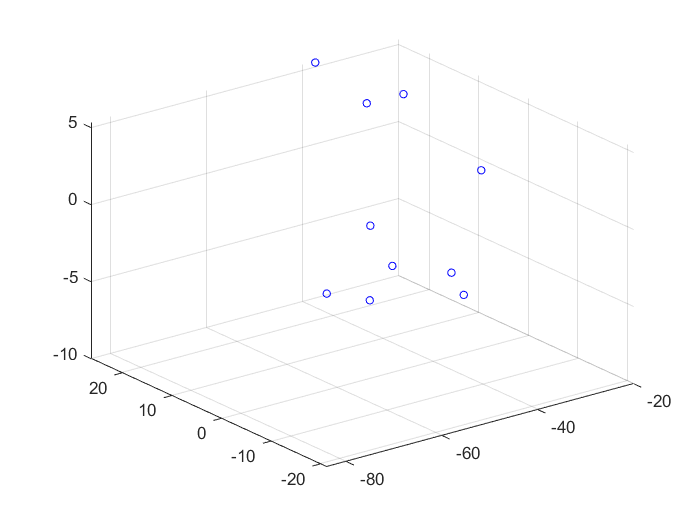

PC1=zeros(size(K,1),1);
PC2=zeros(size(K,1),1);
PC3=zeros(size(K,1),1);
figure 
for i=1:size(K,1)
    x=V(:,1)'*K(i,:)';
    y=V(:,2)'*K(i,:)';
    z=V(:,3)'*K(i,:)';
    PC1(i)=x;
    PC2(i)=y;
    PC3(i)=z;
    scatter3(x,y,z,20,'blue');
    %scatter(x,y,20,"black")
    hold on
end

PC1,PC2,PC3

PC1 =   -51.8398
  -84.1366
  -46.9139
  -37.8218
  -35.6869
  -37.3189
  -35.0842
  -43.9558
  -31.1844
  -41.2196


PC2 =   -15.2735
  -21.3327
    5.8563
   15.3665
   12.2690
   26.2415
   10.6067
  -13.6651
    2.2120
   11.4778


PC3 =    -0.9994
    1.2551
   -1.4867
    4.2866
   -5.9895
    5.2811
    5.3518
    4.7461
   -6.7644
   -7.6408
